%% System Parameters and Initialization
clc;
clear all;
close all;

% Simulation settings
no_of_independent_trials = 10;
no_of_inputs = 1e6;  

% FLANN and input settings
N = 15;              % Input buffer length
fln_order = 2;       % FLANN Order

% Adaptation step sizes
mu1 = 0.01;         % Step size for FLANN1
mu2 = 0.001;        % Step size for FLANN2
mu_lambda = 0.005;  % Adaptation rate for the mixing parameter (via alpha)

% Initialize the auxiliary variable for lambda
alpha_init = 0;     % alpha = 0 corresponds to lambda = 0.5

%% Pre-allocation for Storing Results
err_combined = zeros(no_of_independent_trials, no_of_inputs);
err1 = zeros(no_of_independent_trials, no_of_inputs);
err2 = zeros(no_of_independent_trials, no_of_inputs);
lambda_all = zeros(no_of_independent_trials, no_of_inputs);

%% Main Loop Over Independent Trials
for itr = 1:no_of_independent_trials
    clc;
    fprintf('Independent Trial No: %d/%d\n', itr, no_of_independent_trials);
    
    %% Input and Noise Generation
    % Generate and normalize input signal (zero mean, unit variance)
    input = rand(1, no_of_inputs) - 0.5;
    input = (input - mean(input)) / std(input);
    
    % Generate additive white Gaussian noise (AWGN)
    noise = awgn(input, 30) - input;
    
    %% Buffer and FLANN Weights Initialization
    x_buffer = zeros(1, N);
    M = (2 * fln_order + 1) * N + 1;  % Total number of FLANN weights (including bias)
    fln_weights1 = zeros(1, M);         % FLANN1 weights
    fln_weights2 = zeros(1, M);         % FLANN2 weights
    
    % Initialize histories for current trial
    lambda_history = zeros(1, no_of_inputs);
    error_combined = zeros(1, no_of_inputs);
    error1_history = zeros(1, no_of_inputs);
    error2_history = zeros(1, no_of_inputs);
    
    % Initialize the mixing parameter auxiliary variable
    alpha = alpha_init;
    
    %% Loop Over Each Input Sample (Processing and Adaptation)
    for i = 1:no_of_inputs
        % Update the input buffer (FIFO structure)
        x_buffer = [input(i), x_buffer(1:end-1)];
        
        % --- System: Desired Output Generation ---
        % Nonlinear mapping: q = 1.5*x - 0.3*x^2 with conditional gain rho
        q = 1.5 * input(i) - 0.3 * input(i)^2;
        rho = 4 * (q > 0) + 0.5 * (q <= 0);
        desired_output = 2 * ((1 / (1 + exp(-rho * q))) - 0.5) + noise(i);
        
        % --- FLANN Feature Expansion ---
        % Construct the feature vector using sine and cosine functions
        FEB = [];
        for k = 1:fln_order
            FEB = [FEB, sin(pi * k * x_buffer), cos(pi * k * x_buffer)];
        end
        % Include bias term and raw input buffer along with FLANN expansion
        fln_input = [1, x_buffer, FEB];
        
        % --- FLANN 1 Processing ---
        % Compute output and error for FLANN1
        fln_output1 = fln_weights1 * fln_input';
        error1 = desired_output - fln_output1;
        
        % --- FLANN 2 Processing ---
        % Compute output and error for FLANN2
        fln_output2 = fln_weights2 * fln_input';
        error2 = desired_output - fln_output2;

        % --- Convex Combination (Adaptive Mixing) ---
        % Calculate lambda from the logistic function of alpha
        lambda = 1 / (1 + exp(-alpha));
        % Combined filter output (convex combination of FLANN outputs)
        output_combined = lambda * fln_output1 + (1 - lambda) * fln_output2;
        error_combined(i) = desired_output - output_combined;
        
        % --- Weight Updates for FLANN Filters ---
        % Update FLANN1 weights
        fln_weights1 = fln_weights1 + 2 * mu1 * error1 * fln_input;
        % Update FLANN2 weights
        fln_weights2 = fln_weights2 + 2 * mu2 * error2 * fln_input;
        
        % Adjust the auxiliary variable alpha to update lambda based on error difference
        alpha = alpha + 2 * mu_lambda * error_combined(i) * (fln_output1 - fln_output2) * lambda * (1 - lambda);
        
        % Store the current lambda and squared errors for later analysis
        lambda_history(i) = lambda;
        error1_history(i) = error1^2;
        error2_history(i) = error2^2;
    end
    
    % Save the trial results for each independent run
    err_combined(itr, :) = error_combined .^ 2;
    err1(itr, :) = error1_history;
    err2(itr, :) = error2_history;
    lambda_all(itr, :) = lambda_history;
end

Independent Trial No: 1/10
Independent Trial No: 2/10
Independent Trial No: 3/10
Independent Trial No: 4/10
Independent Trial No: 5/10
Independent Trial No: 6/10
Independent Trial No: 7/10
Independent Trial No: 8/10
Independent Trial No: 9/10
Independent Trial No: 10/10


%% Smoothing Operation for Visualization
smooth_len = 200;
b = ones(1, smooth_len) / smooth_len;
for itr = 1:no_of_independent_trials
    err_combined_smooth(itr, :) = filter(b, 1, err_combined(itr, :));
    err1_smooth(itr, :) = filter(b, 1, err1(itr, :));
    err2_smooth(itr, :) = filter(b, 1, err2(itr, :));
end

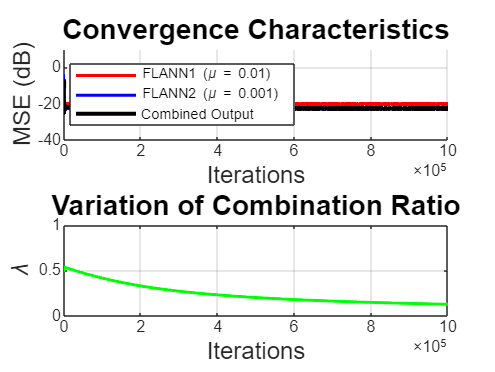

%% Plot Results and Display Final Performance Metrics
% Plot the convergence characteristics (MSE in dB vs. Iterations)
figure('Position', [100, 100, 800, 600]);
subplot(2, 1, 1);
hold on;
plot(10 * log10(mean(err1_smooth)), 'r', 'LineWidth', 1.5);
plot(10 * log10(mean(err2_smooth)), 'b', 'LineWidth', 1.5);
plot(10 * log10(mean(err_combined_smooth)), 'k', 'LineWidth', 2);
xlabel('Iterations', 'FontSize', 12);
ylabel('MSE (dB)', 'FontSize', 12);
title('Convergence Characteristics', 'FontSize', 14);
legend(['FLANN1 (\mu = ' num2str(mu1) ')'], ...
       ['FLANN2 (\mu = ' num2str(mu2) ')'], ...
       'Combined Output', 'Location', 'best');
grid on;
ylim([-40, 10]);
hold off;

% Plot the variation of the mixing parameter lambda vs. iterations
subplot(2, 1, 2);
plot(mean(lambda_all), 'g', 'LineWidth', 1.5);
xlabel('Iterations', 'FontSize', 12);
ylabel('\lambda', 'FontSize', 12);
title('Variation of Combination Ratio', 'FontSize', 14);
ylim([0, 1]);
grid on;


% Display final performance metrics over the last 1000 iterations
epsilon = 1e-20;  % Small constant to avoid log of zero
fprintf('\nFinal MSE values (last 1000 iterations):\n');


Final MSE values (last 1000 iterations):


fprintf('FLANN1 (mu=%.3f): %.2f dB\n', mu1, 10*log10(mean(mean(err1(:, end-1000:end)) + epsilon)));

FLANN1 (mu=0.010): -20.26 dB


fprintf('FLANN2 (mu=%.3f): %.2f dB\n', mu2, 10*log10(mean(mean(err2(:, end-1000:end)) + epsilon)));

FLANN2 (mu=0.001): -22.70 dB


fprintf('Combined output: %.2f dB\n', 10*log10(mean(mean(err_combined(:, end-1000:end)) + epsilon)));

Combined output: -22.62 dB
